# Elliptic Equation - Laplace (Finite Difference approach) - **small scale**

In this example we'll solve a partial differential equation for a **2D Steady State heat conduction** problem.  We'll solve this problem using 2 different approaches  

- via the PDE toolbox 

- via A Finite Difference approach - which we'll develop from scratch

 **So what's the "new" thing that we'll review in this example ?**

With the Finite Difference approach:

- We'll use a data container called a [`table`](matlab:  web(fullfile(docroot, 'matlab/ref/table.html')))  to ***store*** our system of equations  - this makes formulating a solution **soooo easy !**

- We'll ALSO use a data container called a [`table`](matlab:  web(fullfile(docroot, 'matlab/ref/table.html')))  as our mechanism to **"Look up" information about our NODES.**

-  **NOTE:**   this approach is sensible for systems having O(${10}^3$) NODES.  For a grid with many more NODES (e.g.: O(${10}^4$)  NODES) you should look at the solutions contained in [`bh_solution_LARGE_scale_using_table_LOOKUP.mlx`](matlab: edit   bh_solution_LARGE_scale_using_table_LOOKUP.mlx) or [`bh_solution_LARGE_scale_using_dictionary.mlx`](matlab:  edit  bh_solution_LARGE_scale_using_dictionary.mlx)

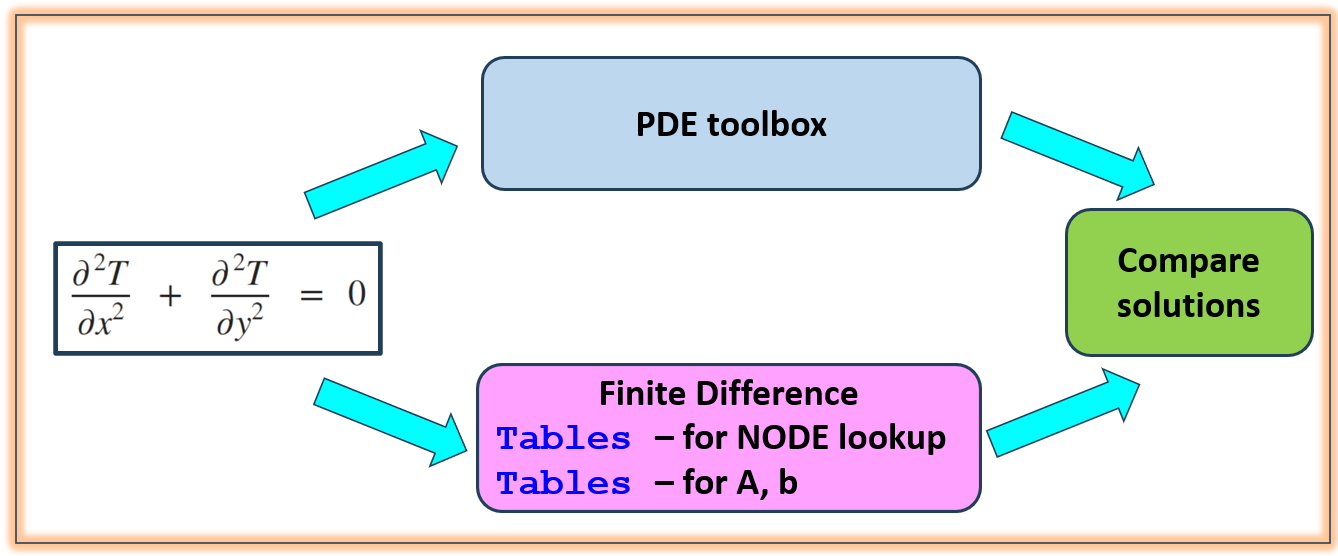

## The system to be studied:

Consider the following pde - it represents the partial differential equation for a 2D **Steady State** heat conduction problem

- $\frac{\partial^{\;2} T}{\partial x^2 }\;\;+\;\;\frac{\partial^{\;2} T}{\partial y^2 }\;\;=\;\;0$       where $T\left(x,y\right)$ is the temperature of a plate 

We'll consider the domain and Boundary conditions listed below - our domain is a square plate with side length $W$

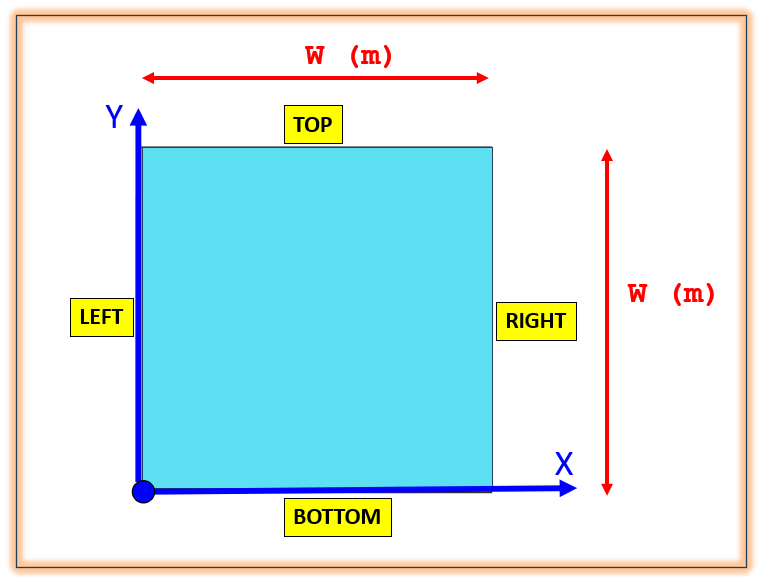

**DOMAIN:**

-     square plate $\left(0\le x\le W\right)$ and $\left(0\le y\le W\right)$

**BOUNDARY Conditions:**

- $\frac{\partial T}{\partial x}=0$  for $x=0\;\;\;\Longrightarrow$   **LEFT** Edge

- $\frac{\partial T}{\partial y}=0$  for $y=0\;\;\;\Longrightarrow$   **BOTTOM** Edge 

- $T=2\ldotp \left|x-0\ldotp 5\right|\;\;\;\;\;\;\;\Longrightarrow \;\;\;$**TOP** Edge 

- $T=y\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\Longrightarrow$   **RIGHT** Edge 

## **Clear your workspace**

Start with a clean slate and delete any variables in your MATLAB workspace

clear

# **PDE Toolbox approach:**

First we'll solve this problem using the [**Partial Differential Equation Toolbox**](matlab:  web(fullfile(docroot, 'pde/index.html'))) for MATLAB.  The following DOC pages are worth reviewing

- [`createpde()`](matlab:  web(fullfile(docroot, 'pde/ug/createpde.html'))) : create a PDE model

- [`decsg()`](matlab:  web(fullfile(docroot, 'pde/ug/decsg.html')))** : **Decompose constructive solid 2-D geometry into minimal regions

- [`geometryFromEdges()`](matlab:  web(fullfile(docroot, 'pde/ug/pde.pdemodel.geometryfromedges.html')))  :  Create 2-D geometry from decomposed geometry matrix

- **TIP:**  study [**THIS**](matlab:  web(fullfile(docroot, 'pde/ug/constant-boundary-condition-specifications.html'))) shipping example for tips on using decsg()

## **Define the square's geometry**

In this example, we're considering a square plate with side length $W$

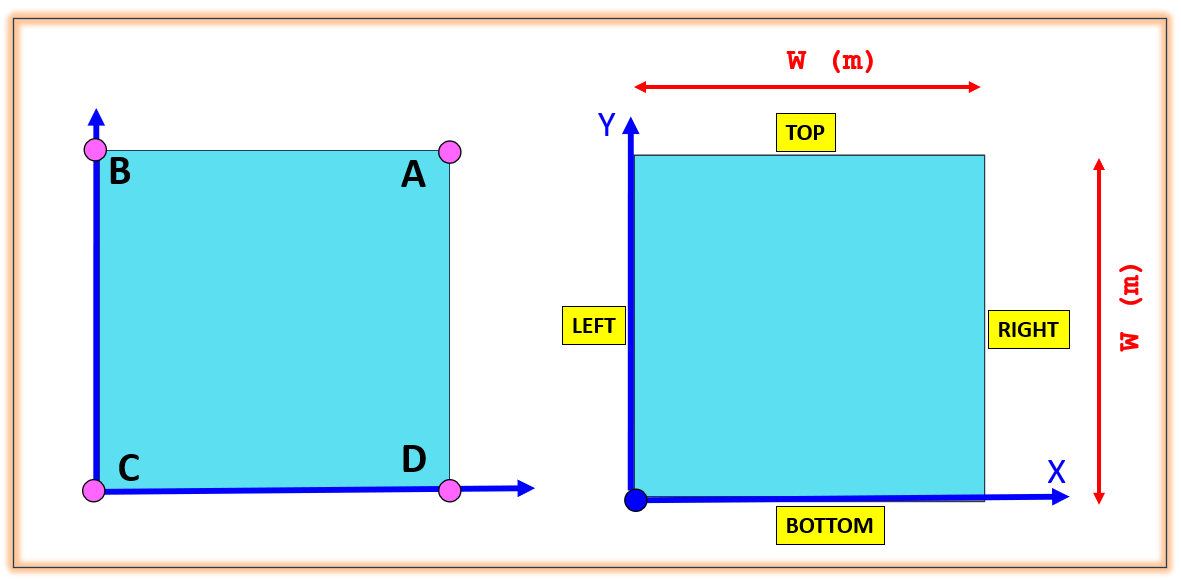

PLATE_WIDTH    = 1;               % dimension of the plate

Define the $\left(x,y\right)$ co-ordinates of the vertices of the square plate - see [`decsg()`](matlab:  web(fullfile(docroot, 'pde/ug/decsg.html')))

 **NOTE:  **specifying the verticies in the order $A\longrightarrow B\longrightarrow C\longrightarrow D$ will produce a geometry model with the following EDGES:

- TOP edge $\longrightarrow \textrm{E1}$

- LEFT edge $\longrightarrow \textrm{E2}$

- BOTTOM edge $\longrightarrow \textrm{E3}$

- RIGHT edge $\longrightarrow \textrm{E4}$

              %  A             B             C   D
R1    = [3,4,    PLATE_WIDTH,  0,            0,  PLATE_WIDTH,  ....
                 PLATE_WIDTH,  PLATE_WIDTH,  0,  0]' ;

g     = decsg(R1);

### Create the PDE model

model = createpde;

geometryFromEdges(model, g);

### Plot the domain ... and see the edge labels

NOTE the edge labels assigned to the square - we'll need these edge labels when we define the boundary conditions

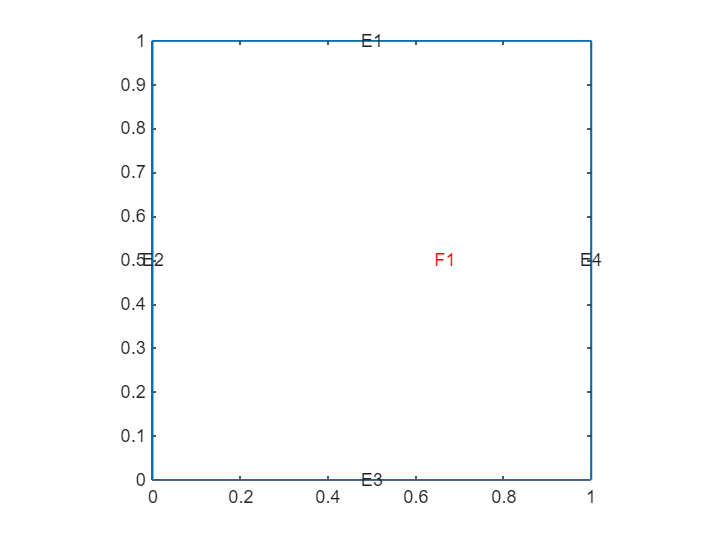

figure;
    pdegplot(model,'EdgeLabels','on','SubdomainLabels','on')
        axis equal   

## Set the Boundary conditions

- $\frac{\partial T}{\partial x}=0$  for $x=0\;\;\textrm{and}\;0<y<W\;\;\Longrightarrow$   Edge **E2  (LEFT)**

- $\frac{\partial T}{\partial y}=0$  for $y=0\;\;\textrm{and}\;0<x<W\;\;\Longrightarrow$   Edge **E3  (BOTTOM)**

- $T=2\ldotp \left|x-0\ldotp 5\right|\;\;\;\;\Longrightarrow \;\;\;$Edge **E1 (TOP)**

- $T=y\;\;\;\;\Longrightarrow$   Edge **E4 (RIGHT)**

Implement these Boundary Conditions using the [`applyBoundaryCondition()`](matlab:  web(fullfile(docroot, 'pde/ug/pde.pdemodel.applyboundarycondition.html'))) function

-  : **CONFIRM** from the previous plot that the EDGE label IDs are indeed correct !

applyBoundaryCondition(model, "Neumann",   "Edge", [2,3]);  % for LEFT and BOTTOM edges
applyBoundaryCondition(model, "Dirichlet", "Edge", 1, "u", @(loc, state)2*abs(loc.x-0.5)); % for TOP edge
applyBoundaryCondition(model, "Dirichlet", "Edge", 4, "u", @(loc, state) loc.y);  % for RIGHT edge

## Specify the TYPE of PDE that you want to solve, 

We will use the [`specifyCoeffecients()`](matlab:  web(fullfile(docroot, 'pde/ug/pde.pdemodel.specifycoefficients.html'))) function to define the exact PDE that we want to solve - ie: specify the co-effiecients **m,d,c,a,f**

- 
$$m\frac{\partial^{\;2} T}{\partial t^2 }\;\;+\;\;d\ldotp \frac{\partial T}{\partial t}\;\;-\;\nabla \ldotp \left(c\ldotp \nabla T\right)\;\;+\;a\ldotp T=\;f$$


We specifically want to solve:

- $-1\;\;\ldotp \;c\ldotp \left(\frac{\partial^{\;2} T}{\partial x^2 }\;\;+\;\;\frac{\partial^{\;2} T}{\partial y^2 }\right)\;\;=\;\frac{\partial^{\;2} T}{\partial x^2 }\;\;+\;\;\frac{\partial^{\;2} T}{\partial y^2 }\;\;=\;\;0$      so   $c\;=\;-1$

specifyCoefficients(model,"m",0,"d",0,"c",-1,"a",0,"f",0);

## Generate the mesh

Generate the finite element mesh using [`generateMesh()`](matlab:  web(fullfile(docroot, 'pde/ug/pde.pdemodel.generatemesh.html')))

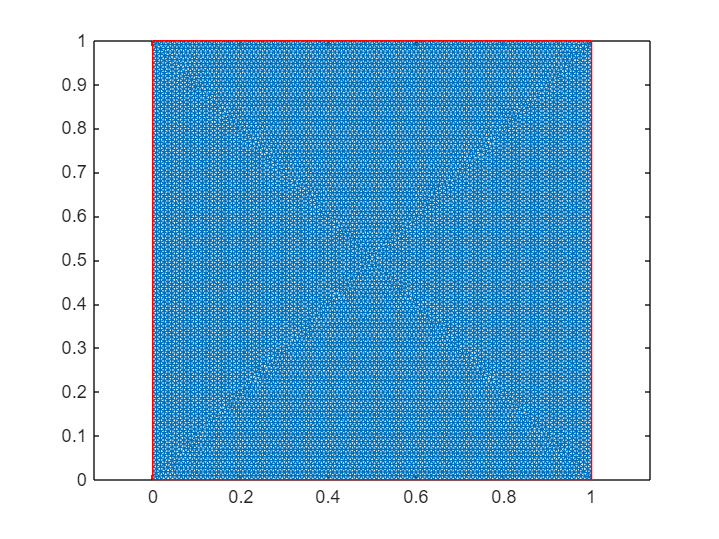

hmax = 0.01;  % a target value for the longest MESH edge length 

generateMesh(model,"Hmax",hmax,"GeometricOrder","linear");

figure
    pdeplot(model)

## Calculate the Solution

Use the [`solve`](matlab:  web(fullfile(docroot, 'pde/ug/pde.thermalmodel.solve.html'))) function to calculate the solution.

PDE_solution = solvepde(model);

## Visualise the solution

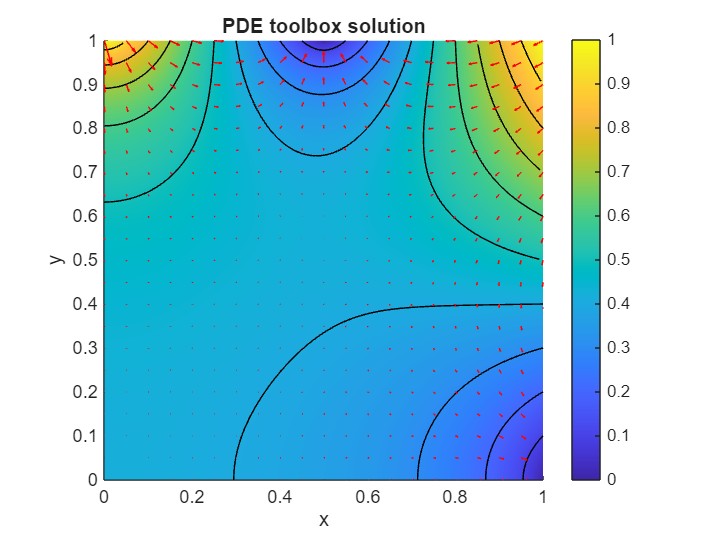

tmp_T_min = min(PDE_solution.NodalSolution);
tmp_T_max = max(PDE_solution.NodalSolution);
PDE_sol_T_contour_levels = linspace(tmp_T_min, tmp_T_max, 11);

figure
    pdeplot(model, FlowData=[-PDE_solution.XGradients, -PDE_solution.YGradients], ...
            XYData=PDE_solution.NodalSolution, colormap='parula', ...
            contour='on', levels=PDE_sol_T_contour_levels)
    axis image
    axis([0,1,0,1])
    xlabel("x")
    ylabel("y")
    title("PDE toolbox solution")

# **Finite Difference approach:**

Now let's solve this exact same problem again .... but using a Finite Difference scheme.  The Finite difference stencil for solving our problem has been derived [**HERE**](matlab:  edit  bh_deriv_for_2d_pde_ellip_heat_ss.mlx) , and for ***internal*** nodes on our plate, the stencil has the form:

-   $T_{i+1,\;j} \;\;+\;\;\;T_{i-1,\;j} \;\;+\;\;\;T_{i,\;j+1} \;\;+\;\;\;T_{i,\;j-1} \;\;\;-\;\;\;4\ldotp T_{i\;\;,\;j} =0$     where    $T_{i\;\;,\;j} =T\left(\;x_i \;\;,y_j \;\right)$

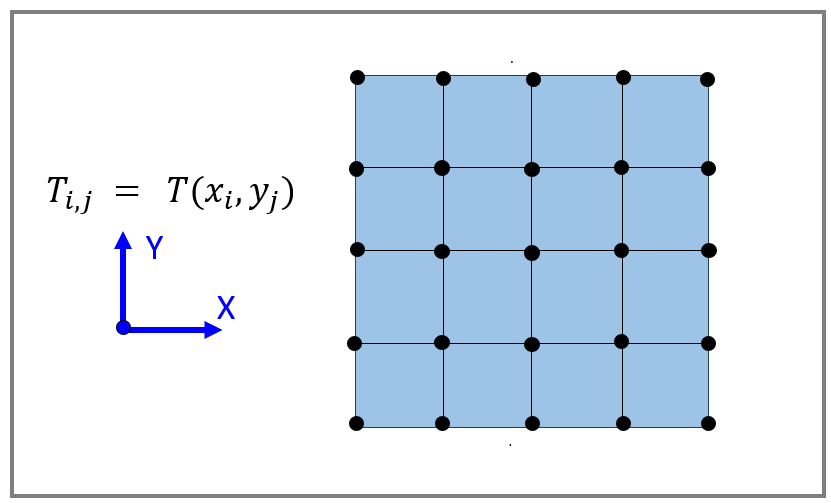

In the Finite Difference approach, we need to write out a stencil equation for ALL nodes in our domain.

- For the INTERNAL nodes we can use the stencil stated above

- For nodes on the plate's BOUNDARY, we'll need to modify this default stencil

Once we've written out the appropriate stencil equation for each node, we'll represent this SYSTEM of equations in matrix form as:

- $A\ldotp x=b$     where    $x$ are the node temperatures

In MATLAB, a problem in the form $A\ldotp x=b$ is solved using the famous "backslash" operator, i.e.:  $x=A\;\;\backslash \;\;b$

## **Define the Grid size**

Slice the square plate into a Grid.  The grid will contain ***n*** intervals in both the X and Y directions

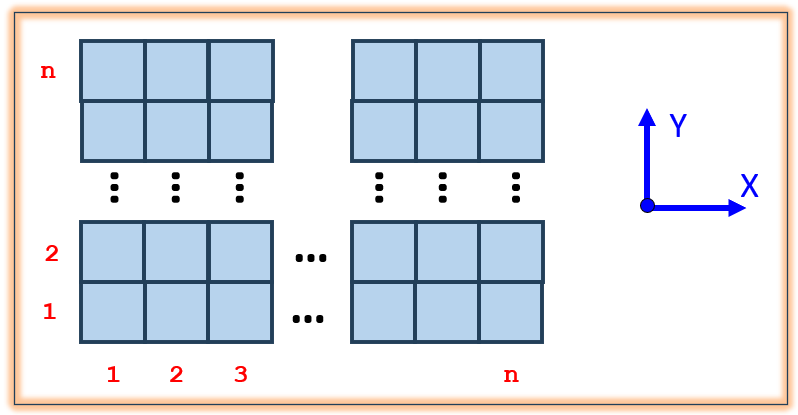

**ATTENTION:  **

-  only a SMALL number of INTERVALS will be considered here

- IFF you want to see a solution using more INTERVALS, please see  [`bh_solution_LARGE_scale_using_table_LOOKUP.mlx`](matlab: edit   bh_solution_LARGE_scale_using_table_LOOKUP.mlx)

n              = 50; % NUM intervals
assert(n<=50, "only a SMALL number of INTERVALS will be considered here");

h    = PLATE_WIDTH/n;   % SPATIAL step  (same in X, and Y directions)

Npt  = n + 1;           % number of points in each of x, y directions
Ndof = Npt*Npt;         % total number of GRID points

### **Define the grid points**

x  = linspace(0, PLATE_WIDTH, Npt); % to generate equally spaced (n + 1) points in x
y  = linspace(0, PLATE_WIDTH, Npt); % to generate equally spaced (n + 1) points in y

So we now have a collection of grid points .... which we'll call **NODES**.  Consider for example the plate shown below - 4 intervals in the X and Y directions.

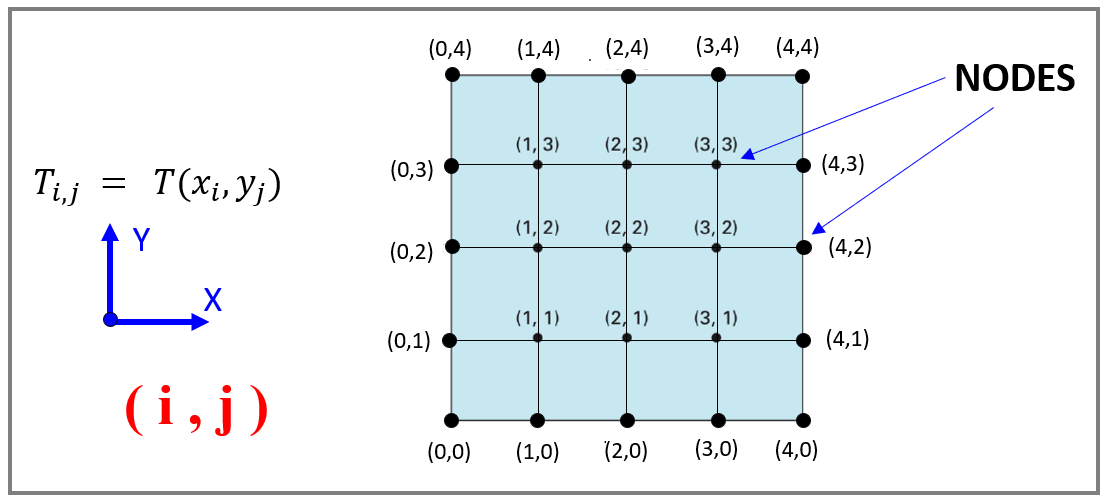

For each NODE, observe the following:

- A NODE has an ID - say $i,j$

- A NODE has Co-ordinates $\left(x_i \;\;\;,\;y_j \right)$

- A NODE has a Temperature  $T_{i\;\;,\;j}$

- Some NODES are BOUNDARY condition nodes 

- Some NODES are INTERNAL nodes 

 For each NODE we can either:

-  write out the Finite Difference stencil      $T_{i+1,\;j} \;\;+\;\;\;T_{i-1,\;j} \;\;+\;\;\;T_{i,\;j+1} \;\;+\;\;\;T_{i,\;j-1} \;\;\;-\;\;\;4\ldotp T_{i\;\;,\;j} =0$  (see derivation [**HERE**](matlab:  edit  bh_deriv_for_2d_pde_ellip_heat_ss.mlx)) 

- **OR** we can write out the stencil that incorporates our Boundary Condition

We can then collect/organise these equations in MATRIX form.  The MATRIX form of our system will have the shape: 

-   
$$A\;\ldotp z=\textrm{rhs}$$
 

where:

- 
$$\textrm{transpose}\left(z\right)=\left\lbrack T_{0,0} \;\;T_{1,0} \;\;T_{2,0} \;\;T_{3,0} \;\;T_{4,0} ,\cdots \;\;\;\;\;\;\;T_{0,1} \;\;T_{1,1} \;\;T_{2,1} \;\;T_{3,1} \;\;T_{4,1} ,\cdots \;\;\;\;\;\;T_{0,2} \;\;T_{1,2} \;\;T_{2,2} \;\;T_{3,2} \;\;T_{4,2} ,\cdots \;\;\;\;\;\;\;T_{0,3} \;\;T_{1,3} \;\;T_{2,3} \;\;T_{3,3} \;\;T_{4,3} ,\cdots \;\;\;\;\;\;\;\;\right\rbrack \;$$


Once we have our system MATRICES $A$ and $\textrm{rhs}$, we can then solve for the unknown temperatures via:    $z=A\;\backslash \;\textrm{rhs}$

## Book keeping preparation - using a `table`

Before we attack this problem, let's do a little bit of book keeping - aka setting up some data containers that will make it ***soooo much easier*** to understand how to solve the problem.  Specifcally we will:

- Define a  [`table`](matlab:  web(fullfile(docroot, 'matlab/ref/table.html')))  data type to act as our mechanism to **"Look up" **information about our** NODES**

- Define a [`table`](matlab:  web(fullfile(docroot, 'matlab/ref/table.html'))) data type to **store** our system of equations

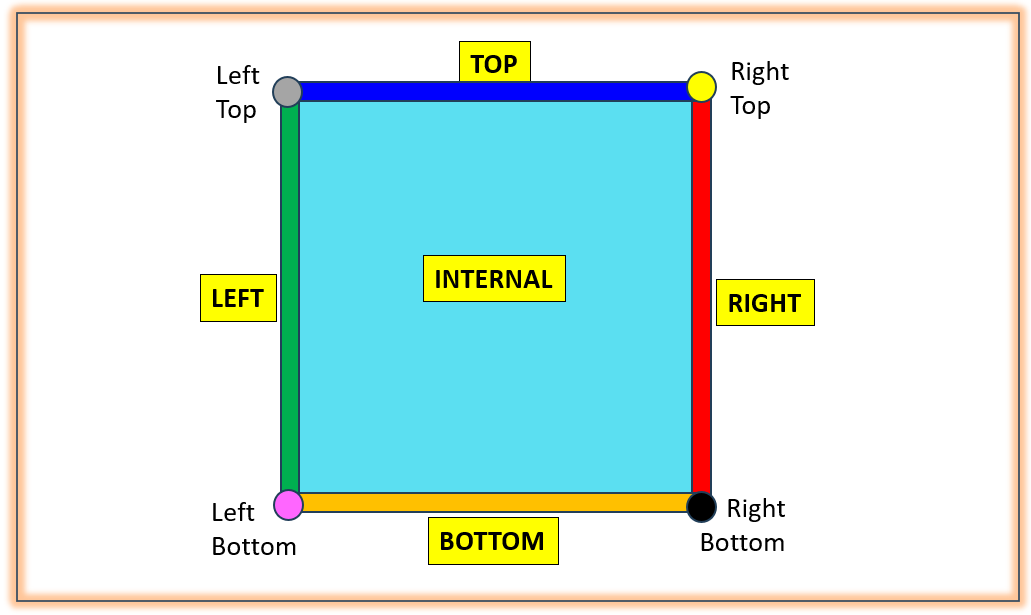

Recall that the Nodes in our grid can be one of 9 different types, where each type corresponds to either an INTERNAL node OR a node with a specific type of Boundary Condition.  The 9 node types are

- INTERNAL

- BC_RIGHT

- BC_RIGHT_TOP

- BC_RIGHT_BOTTOM

- BC_TOP

- BC_LEFT_TOP

- BC_LEFT

- BC_LEFT_BOTTOM

- BC_BOTTOM

A NODE **Lookup table **will allow us to extract information about a **NODE** using "plain english" indexing.  The properties that we'll store (and retrieve) from our Lookup table will include:

For example, the columns of our **Lookup table** will look like this:

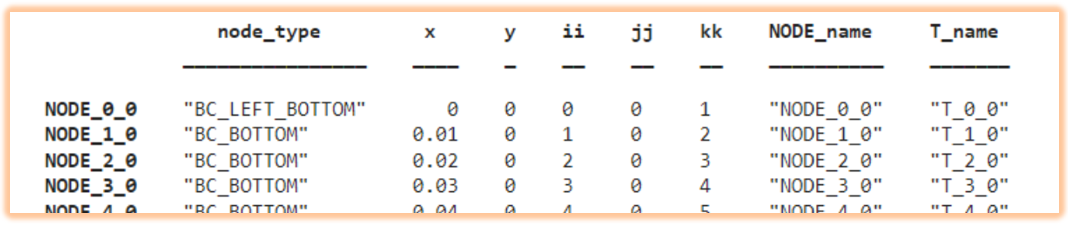

So ? - So if we wanted to extract the x-cordinate of say the "NODE_3_0" node, we'd use syntax such as this:

### Create a NODE Lookup table

We'll create the NODE Lookup table via the function [`bh_create_node_lookup()`](matlab:  edit bh_create_node_lookup)`.`  

[NODE_name_list, NODE_PROP_LOOKUP_TAB] = bh_create_node_lookup(x, y, "mode", "table");

whos NODE_name_list NODE_PROP_LOOKUP_TAB

  Name                         Size             Bytes  Class     Attributes

  NODE_PROP_LOOKUP_TAB      2601x8             930381  table               
  NODE_name_list            2601x1             182182  string              



So here's the first few rows of our node lookup table

head(NODE_PROP_LOOKUP_TAB)

                   node_type         x      y    ii    jj    kk    NODE_name     T_name 
                ________________    ____    _    __    __    __    __________    _______

    NODE_0_0    "BC_LEFT_BOTTOM"       0    0    0     0     1     "NODE_0_0"    "T_0_0"
    NODE_1_0    "BC_BOTTOM"         0.02    0    1     0     2     "NODE_1_0"    "T_1_0"
    NODE_2_0    "BC_BOTTOM"         0.04    0    2     0     3     "NODE_2_0"    "T_2_0"
    NODE_3_0    "BC_BOTTOM"         0.06    0    3     0     4     "NODE_3_0"    "T_3_0"
    NODE_4_0    "BC_BOTTOM"         0.08    0    4     0     5     "NODE_4_0"    "T_4_0"
    NODE_5_

### Create some SYSTEM tables

in just a moment we're going to construct a matrix problem that has the shape:

-   $A\;\ldotp z=\textrm{rhs}$     where     $z={\left\lbrack T_{0,0} \;\;T_{1,0} \;\;T_{2,0} \;\;T_{3,0} \;\;T_{4,0} ,\cdots \;\;\;\;\;\;\;T_{0,1} \;\;T_{1,1} \;\;T_{2,1} \;\;T_{3,1} \;\;T_{4,1} ,\cdots \;\;\;\;\;\;T_{0,2} \;\;T_{1,2} \;\;T_{2,2} \;\;T_{3,2} \;\;T_{4,2} ,\cdots \;\;\;\;\;\;\;\right\rbrack }^T$

To help with the "book keeping" of assembling our system MATRICES, let's again use a  [`table`](matlab:  web(fullfile(docroot, 'matlab/ref/table.html'))).  We'll label our columns and we'll label our rows.

- The ROW labels will take the form:  `NODE_i_j`

- The COLUMN labels will take the form:  `T_i_j`

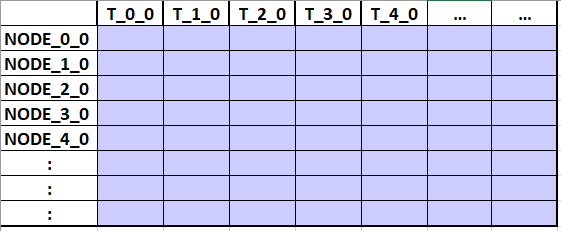

We can then use these meaningful labels to "index" into the table, eg: with TABLES we can do stuff like this:

Populate our $A$ and $\textrm{rhs}$ Tables  with **ZERO** values:

A_TAB   = array2table( zeros(Ndof, Ndof),  "RowNames",NODE_PROP_LOOKUP_TAB.NODE_name, "VariableNames",  NODE_PROP_LOOKUP_TAB.T_name);
rhs_TAB = array2table( zeros(Ndof,1),      "RowNames",NODE_PROP_LOOKUP_TAB.NODE_name, "VariableNames", "T");

whos A_TAB   rhs_TAB

  Name            Size                 Bytes  Class    Attributes

  A_TAB        2601x2601            55018241  table              
  rhs_TAB      2601x1                 342269  table              



## Visualize the grid

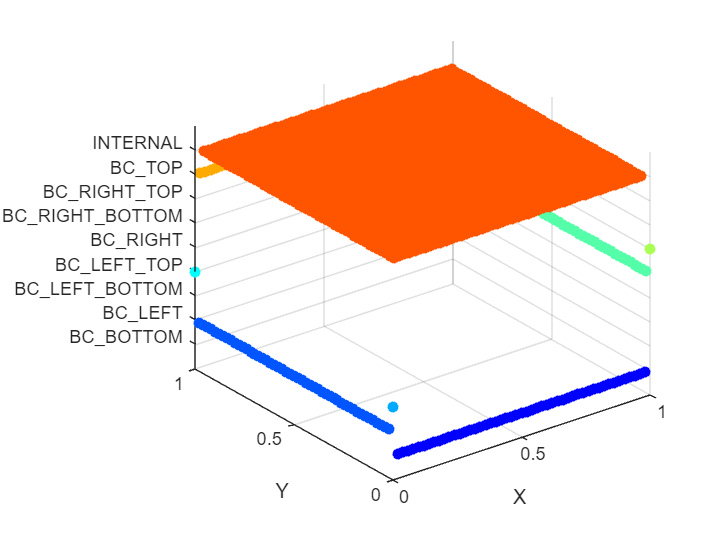

     BC_BOTTOM              49 
     BC_LEFT                49 
     BC_LEFT_BOTTOM          1 
     BC_LEFT_TOP             1 
     BC_RIGHT               49 
     BC_RIGHT_BOTTOM         1 
     BC_RIGHT_TOP            1 
     BC_TOP                 49 
     INTERNAL             2401 


LOC_visualize_grid(NODE_PROP_LOOKUP_TAB)

## Assemble System of equations

We're now going to assemble a system of equations of the form:

- 
$$A\ldotp x=b$$


So let's process each NODE in our grid and recall that an INTERNAL node has an equation of the form:

-   $T_{i+1,\;j} \;\;+\;\;\;T_{i-1,\;j} \;\;+\;\;\;T_{i,\;j+1} \;\;+\;\;\;T_{i,\;j-1} \;\;\;-\;\;\;4\ldotp T_{i\;\;,\;j} =0$     (see derivation [**HERE**](matlab:  edit  bh_deriv_for_2d_pde_ellip_heat_ss.mlx)) 

We'll treat other node types based on the Boundary condition associated with each node.

- 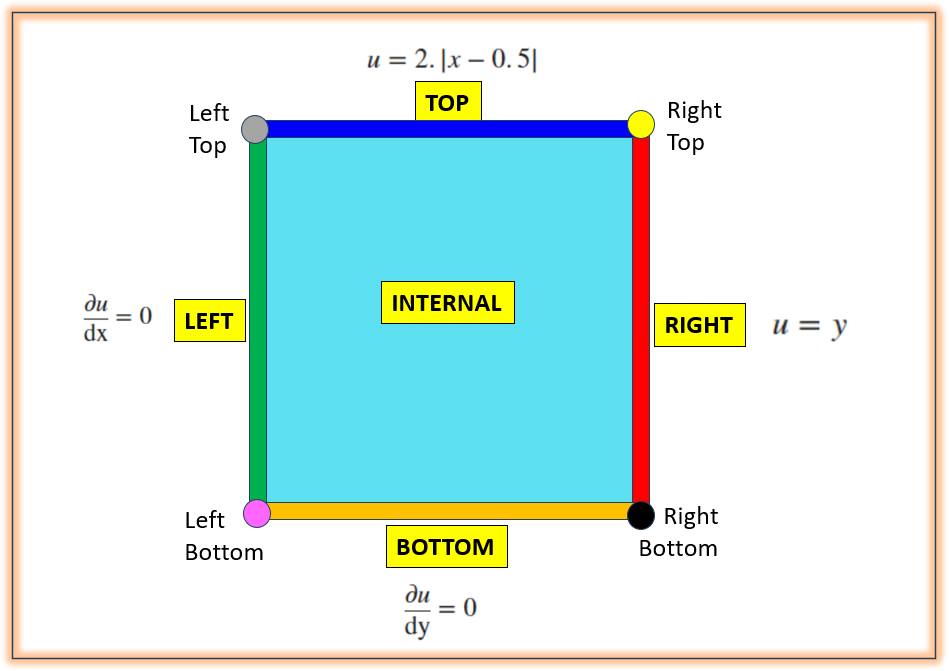

### Process each NODE in our grid

for kk=1:length(NODE_name_list)

    % what NODE are we processing
    NODE_ID_str   = NODE_name_list(kk);

    % pull out the properties of this node from our LOOKUP table
    NODE_TYPE    = NODE_PROP_LOOKUP_TAB.node_type(kk);
    ii_ID        = NODE_PROP_LOOKUP_TAB.ii(kk);
    jj_ID        = NODE_PROP_LOOKUP_TAB.jj(kk);    
    x_cord       = NODE_PROP_LOOKUP_TAB.x(kk);
    y_cord       = NODE_PROP_LOOKUP_TAB.y(kk);

    % construct the T ID for this node
    T_ID_str      =    "T_"  + ii_ID  + "_" + jj_ID;
   
    % PROCESS the node
    switch(NODE_TYPE)  

If it's an **INTERNAL** node, just use our derived stencil:

- 
$$T_{i+1,\;j} \;\;+\;\;\;T_{i-1,\;j} \;\;+\;\;\;T_{i,\;j+1} \;\;+\;\;\;T_{i,\;j-1} \;\;\;-\;\;\;4\ldotp T_{i\;\;,\;j} =0$$


        case "INTERNAL"    
             A_TAB{NODE_ID_str, ("T_" + (ii_ID+1) + "_" +  jj_ID)   } =  1;
             A_TAB{NODE_ID_str, ("T_" + (ii_ID-1) + "_" +  jj_ID)   } =  1; 
             A_TAB{NODE_ID_str, ("T_" +  ii_ID    + "_" + (jj_ID+1))} =  1;           

  Name         Size                 Bytes  Class     Attributes

  A         2601x2601            54121608  double              
  rhs       2601x1                  20808  double              



             A_TAB{NODE_ID_str, ("T_" +  ii_ID    + "_" + (jj_ID-1))} =  1;   
             A_TAB{NODE_ID_str, ("T_" +  ii_ID    + "_" +  jj_ID)   } = -4;   

Regarding the **RIGHT** edge **Boundary Condition**:

- $T=y\;\;\;\;\Longrightarrow$   Edge **E4 (RIGHT)**

  Name              Size                 Bytes  Class     Attributes

  A              2601x2601            54121608  double              
  T_results      2601x1                  20808  double              
  rhs            2601x1                  20808  double              



        case {"BC_RIGHT", "BC_RIGHT_TOP", "BC_RIGHT_BOTTOM" }
                         A_TAB{ NODE_ID_str,   T_ID_str} = 1;
                       rhs_TAB{ NODE_ID_str,   1       } = y_cord;    

Regarding the **TOP** edge **Boundary Condition**:

- $T=2\ldotp \left|x-0\ldotp 5\right|\;\;\;\;\Longrightarrow \;\;\;$Edge **E1 (TOP)**              

             
        case {"BC_TOP", "BC_LEFT_TOP"}

  Name              Size            Bytes  Class     Attributes

  T_results      2601x1             20808  double              



                         A_TAB{ NODE_ID_str,   T_ID_str} = 1;

Npt = 51

                       rhs_TAB{ NODE_ID_str,   1       } = 2*abs(x_cord - 0.5);               

Regarding the **BOTTOM **edge** Boundary Condition **(a NEUMANN BC), we know that for an INTERNAL node we have

- 
$$T_{i+1,\;j} \;\;+\;\;\;T_{i-1,\;j} \;\;+\;\;\;T_{i,\;j+1} \;\;+\;\;\;T_{i,\;j-1} \;\;\;-\;\;\;4\ldotp T_{i\;\;,\;j} =0$$


And the Boundary condition for the BOTTOM edge is:

- $\frac{\partial T}{\partial y}=0$  for $y=0\;\;\;$   

We can represent this boundary condition with a Central Difference approximation:

- 
$$\frac{\partial T}{\partial y}\;=\;0\;=\;\frac{T_{i,j+1} -T_{i,j-1} }{2\ldotp \Delta y}\;\;\;\Longrightarrow \;\;\;\;\;\;T_{i,\;j-1} =T_{i,\;j+1}$$
      

So if we use a  GHOST node in the negative Y direction, ie:  $T_{i,\;j-1} =T_{i,\;j+1}$ our INTERNAL node stencil can be written as

- 
$$T_{i+1,\;j} \;\;+\;\;\;T_{i-1,\;j} \;\;+\;\;\;\;\;\;\;\;T_{i,\;j+1} \;\;+\;\;\;\left\lbrace T_{i,\;j-1} \right\rbrace \;\;\;-\;\;\;4\ldotp T_{i\;\;,\;j} \;=\;0$$


- 
$$T_{i+1,\;j} \;\;+\;\;\;T_{i-1,\;j} \;\;+\;\;\;\;\;\;\;\;T_{i,\;j+1} \;\;+\;\;\;\left(T_{i,\;j+1} \;\;\right)\;-\;\;\;4\ldotp T_{i\;\;,\;j} \;\;=\;0$$


- 
$$T_{i+1,\;j} \;\;+\;\;\;T_{i-1,\;j} \;\;+\;\;\;2\ldotp T_{i,\;j+1} \;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;-\;\;\;4\ldotp T_{i\;\;,\;j} \;=\;\;0$$


        case "BC_BOTTOM"
               A_TAB{NODE_ID_str, ("T_" + (ii_ID+1) + "_" +  jj_ID)   } =  1;
               A_TAB{NODE_ID_str, ("T_" + (ii_ID-1) + "_" +  jj_ID)   } =  1; 
               A_TAB{NODE_ID_str, ("T_" +  ii_ID    + "_" + (jj_ID+1))} =  2;           
               A_TAB{NODE_ID_str, ("T_" +  ii_ID    + "_" +  jj_ID)   } = -4;

Similarly for our **LEFT **edge** Boundary Condition **(a NEUMANN BC), we know that for an INTERNAL node we have

- 
$$T_{i+1,\;j} \;\;+\;\;\;T_{i-1,\;j} \;\;+\;\;\;T_{i,\;j+1} \;\;+\;\;\;T_{i,\;j-1} \;\;\;-\;\;\;4\ldotp T_{i\;\;,\;j} =0$$


And the Boundary condition for the LEFT edge is:

- $\frac{\partial T}{\partial x}=0$  for $x=0\;\;\;$   

We can represent this boundary condition with a Central Difference approximation:

- 
$$\frac{\partial T}{\partial x}\;=\;0\;=\;\frac{T_{i+1,j} -T_{i-1,j} }{2\ldotp \Delta x}\;\;\;\Longrightarrow \;\;\;\;\;\;T_{i+1,\;j} =T_{i-1,\;j}$$
      

So if we use a  GHOST node in the negative X direction, ie:  $T_{i-1,\;j} =T_{i+1,\;j}$ our INTERNAL node stencil can be written as

- 
$${\;\;\;\;T}_{i+1,\;j} \;\;+\;\;\;\left\lbrace T_{i-1,\;j} \right\rbrace \;\;+\;\;\;T_{i,\;j+1} \;\;+\;\;T_{i,\;j-1} \;\;\;-\;\;\;4\ldotp T_{i\;\;,\;j} \;=0$$


- 
$${\;\;\;\;T}_{i+1,\;j} \;\;+\;\;\;\left(T_{i+1,\;j} \right)\;\;+\;\;\;T_{i,\;j+1} \;\;+\;\;\;T_{i,\;j-1} \;\;\;-\;\;\;4\ldotp T_{i\;\;,\;j} \;=\;0$$


- 
$$2\ldotp T_{i+1,\;j} \;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;+\;\;\;\;T_{i,\;j+1} \;\;+\;\;\;T_{i,\;j-1} \;\;\;-\;\;\;4\ldotp T_{i\;\;,\;j} \;=0$$


        case "BC_LEFT"

  Name            Size            Bytes  Class     Attributes

  the_T_mat      51x51            20808  double              
  the_x_mat      51x51            20808  double              
  the_y_mat      51x51            20808  double              



             A_TAB{NODE_ID_str, ("T_" + (ii_ID+1) + "_" +  jj_ID)   } =  2;
             A_TAB{NODE_ID_str, ("T_" +  ii_ID    + "_" + (jj_ID+1))} =  1;           
             A_TAB{NODE_ID_str, ("T_" +  ii_ID    + "_" + (jj_ID-1))} =  1;   
             A_TAB{NODE_ID_str, ("T_" +  ii_ID    + "_" +  jj_ID)   } = -4;  


And lastly take care of the **LEFT, BOTTOM** node - this shares our 2 NEUMANN boundary conditions

Recall that using a Central Difference approximation we can write:

-      $\frac{\partial T}{\partial x}\;=\;0\;=\;\frac{T_{i+1,j} -T_{i-1,j} }{2\ldotp \Delta x}\;\;\;\Longrightarrow \;\;\;\;\;\;T_{i+1,\;j} =T_{i-1,\;j}$     AND

-      
$$\frac{\partial T}{\partial y}\;=\;0\;=\;\frac{T_{i,j+1} -T_{i,j-1} }{2\ldotp \Delta y}\;\;\;\Longrightarrow \;\;\;\;\;\;T_{i,\;j+1} =T_{i,\;j-1}$$


So if we use  GHOST nodes in the negative X and Y direction, ie:  $T_{i-1,\;j} =T_{i+1,\;j}$ our INTERNAL node stencil can be written as

- 
$${\;\;\;\;T}_{i+1,\;j} \;\;+\;\;\;\left\lbrace T_{i-1,\;j} \right\rbrace \;\;+\;\;\;T_{i,\;j+1} \;\;+\;\;\left\lbrace T_{i,\;j-1} \right\rbrace \;\;\;-\;\;\;4\ldotp T_{i\;\;,\;j} \;=0$$


- 
$${\;\;\;\;T}_{i+1,\;j} \;\;+\;\;\;\left\lbrace T_{i+1,\;j} \right\rbrace \;\;+\;\;\;T_{i,\;j+1} \;\;+\;\;\left\lbrace T_{i,\;j+1} \right\rbrace \;\;\;-\;\;\;4\ldotp T_{i\;\;,\;j} \;=0$$


- 
$${\;\;\;\;2\ldotp T}_{i+1,\;j} \;\;+\;\;{\;\;\;\;2\ldotp T}_{i,\;j+1} \;\;\;-\;\;\;4\ldotp T_{i\;\;,\;j} \;=0$$


        case "BC_LEFT_BOTTOM"
               A_TAB{NODE_ID_str, ("T_" + (ii_ID+1) + "_" +  jj_ID)   } =  2;
               A_TAB{NODE_ID_str, ("T_" +  ii_ID    + "_" + (jj_ID+1))} =  2;           
               A_TAB{NODE_ID_str, ("T_" +  ii_ID    + "_" +  jj_ID)   } = -4;
        otherwise
            error("###_ERROR:  Bad !")
    end % switch
        
end % for kk

## Compute the solution

To compute the solution, let's pull the data out of the TABLES and assign it to "regular" MATRICES

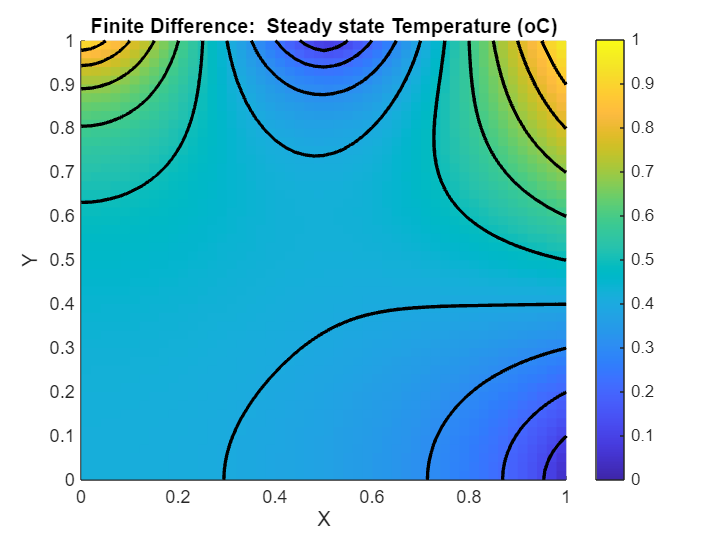

A   =   A_TAB{:,:};
rhs = rhs_TAB{:,1};


whos A rhs

Now solve the system of linear equations   $A\ldotp T_{\textrm{RESULTS}} =\textrm{rhs}$      

 T_results =  A \ rhs;
 whos A rhs T_results

## Visualize the solution

Regarding our solution array `T_results` ,  REMEMBER that the  array contains the values:

-  $\left(\mathit{\mathbf{j}}=0,\;\;i=0\longrightarrow N\right)$           $\left(\mathit{\mathbf{j}}=1,\;\;i=0\longrightarrow N\right)$         $\left(\mathit{\mathbf{j}}=2,\;\;i=0\longrightarrow N\right)$         $\left(\mathit{\mathbf{j}}=3,\;\;i=0\longrightarrow N\right)$  ... etc

- 
$$\left\lbrack T_{0,0} \;\;T_{1,0} \;\;T_{2,0} \;\;T_{3,0} \;\;T_{4,0} \cdots \;\;\;\;\;\;\;T_{0,1} \;\;T_{1,1} \;\;T_{2,1} \;\;T_{3,1} \;\;T_{4,1} \cdots \;\;\;\;\;\;T_{0,2} \;\;T_{1,2} \;\;T_{2,2} \;\;T_{3,2} \;\;T_{4,2} \cdots \;\;\;\;\;\;\;T_{0,3} \;\;T_{1,3} \;\;T_{2,3} \;\;T_{3,3} \;\;T_{4,3} \cdots \;\;\;\;\;\;\;\;T_{0,4} \;\;T_{1,4} \;\;T_{2,4} \;\;T_{3,4} \;\;T_{4,4} \cdots \right\rbrack$$


- where:   $T_{i\;\;,\;j} \;=T\left(x_i \;,y_j \right)$

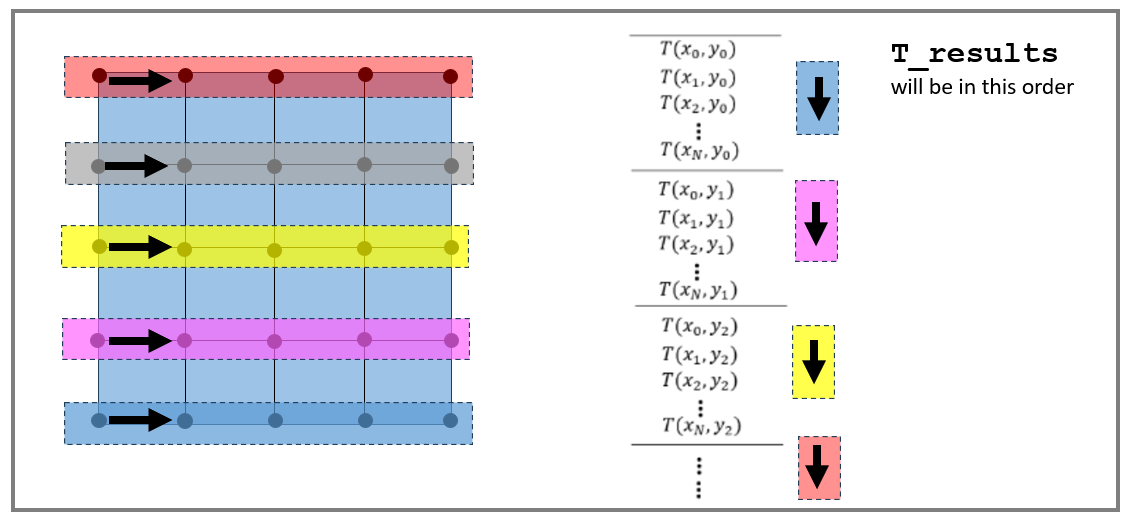

First recall the size and values of some relevant variables:

whos  T_results       
Npt

Let's view our data as a SURFACE.  To do this we need to "shape" our Temperature data array `T_results`, into a MATRIX that is arranged as shown below: (see the DOC on the [`surf()`](matlab:  doc surf) and [`meshgrid()`](matlab: doc meshgrid) functions.)

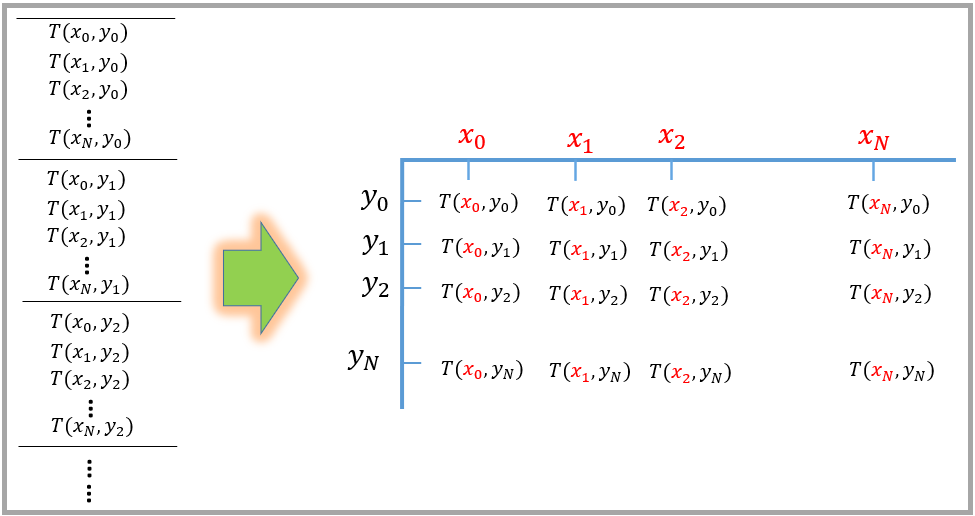

[the_x_mat, the_y_mat] = meshgrid(x, y);

the_T_mat = reshape(T_results, Npt, []);
the_T_mat = the_T_mat';

whos the_x_mat  the_y_mat  the_T_mat

## Plot the Solution as a surface and add contour lines

Let's view our data as a CONTOUR plot - see DOC [`contour`](matlab: doc contour) and [`contour3`](matlab: doc contour3)

We'll overlay contour lines at the same levels as those plotted with the PDE toolbox solution

THE_C_LEVELS = PDE_sol_T_contour_levels;

Now plot the Finite Difference solution

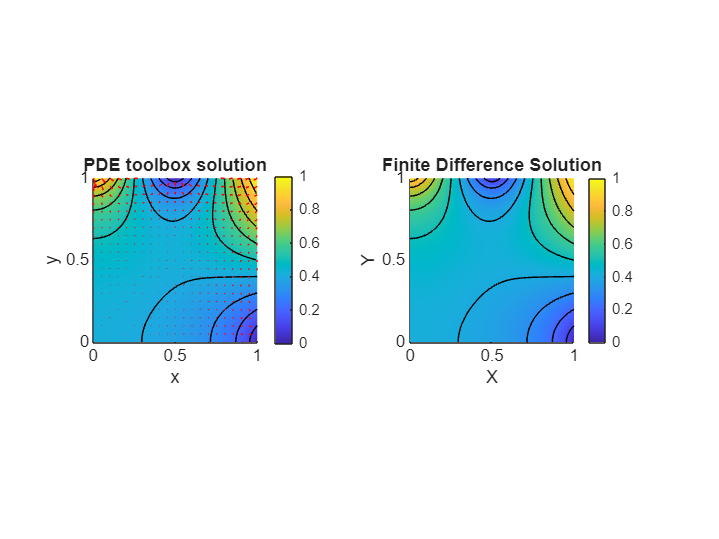

figure;
    surf(the_x_mat, the_y_mat, the_T_mat, "EdgeColor","none"); %, "FaceAlpha",0.7);
       hold("on")
    [~, c_props] = contour3(the_x_mat, the_y_mat, the_T_mat, THE_C_LEVELS,'-k');
        c_props.LineWidth = 2;

            xlabel("X");  ylabel("Y");  zlabel("Temperature (oC)"); 
            colorbar
            colormap(parula)
            view(2)
            title('Finite Difference:  Steady state Temperature (oC)')

# Compare the PDE toolbox solution and our Finite Difference Solution

Let's visually compare the results produced by the** PDE toolbox** against the results produced by our **Finite Difference** approach

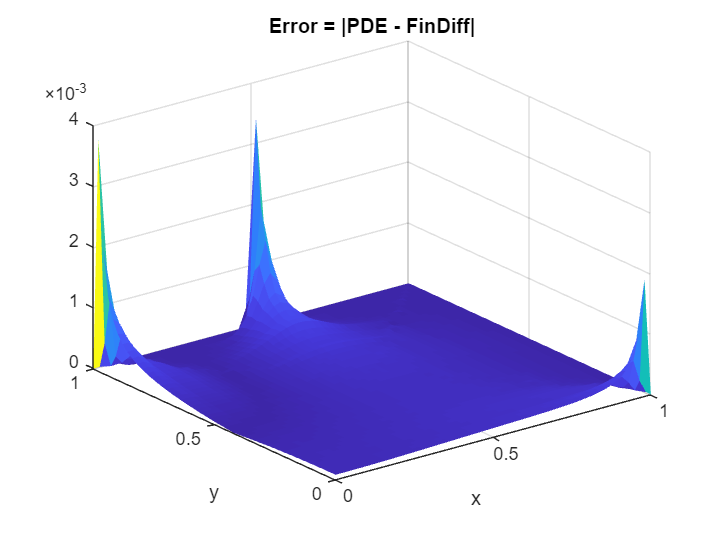

figure
    subplot(1,2,1)
        pdeplot(model, FlowData=[-PDE_solution.XGradients, -PDE_solution.YGradients], ...
                       XYData=PDE_solution.NodalSolution, colormap='parula', ...
                       contour='on', levels=PDE_sol_T_contour_levels)
        axis image
        axis([0,1,0,1])
        xlabel("x")
        ylabel("y")
        title("PDE toolbox solution")     

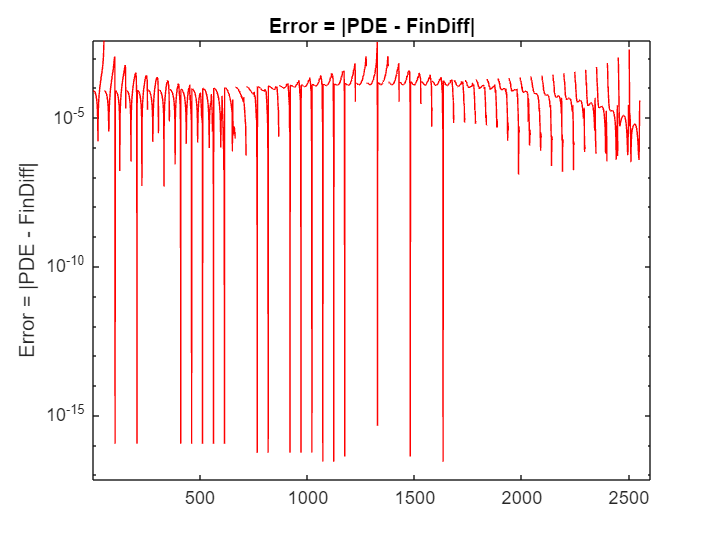


    subplot(1,2,2)
        surf(the_x_mat, the_y_mat, the_T_mat, "EdgeColor","none"); %, "FaceAlpha",0.7);
           hold("on")
        [~, c_props] = contour3(the_x_mat, the_y_mat, the_T_mat, PDE_sol_T_contour_levels,'-k');
            c_props.LineWidth = 0.5;

            xlabel("X");  
            ylabel("Y");  
            colorbar
            colormap(parula)
            view(2)  % birds eye view looking down on surface
            axis equal
            title('Finite Difference Solution')   

Besides "visually" comparing the 2 solutions we can interpolate the PDE toolbox sultion at the NODE points used by our Finite Difference solution ... and then explore the difference between these 2 results

- See the DOC page [`interpolateSolution()`](matlab:  web(fullfile(docroot, 'pde/ug/pde.stationaryresults.interpolatesolution.html')))

T_pde_interp = interpolateSolution(PDE_solution, the_x_mat, the_y_mat);      
T_pde_interp = reshape(T_pde_interp, size(the_T_mat));

T_error = abs(T_pde_interp - the_T_mat);

figure;
   surf(the_x_mat, the_y_mat, T_error, "EdgeColor","none"); %, "FaceAlpha",0.7);
        xlabel("x")
        ylabel("y")
        title("Error = |PDE - FinDiff|") 

And let's flatten this error matrix and plot it on a LOG scale

figure;
    semilogy(T_error(:), "-r");
        ylabel("Error = |PDE - FinDiff|") 
        title("Error = |PDE - FinDiff|") 
        axis tight

# Local SUBfunctions only beyond this point

function LOC_visualize_grid(NODE_PROP_LOOKUP_TAB)

    x_list         = NODE_PROP_LOOKUP_TAB.x;  
    y_list         = NODE_PROP_LOOKUP_TAB.y; 
    NODE_type_list = NODE_PROP_LOOKUP_TAB.node_type;
    
    unique_types     = unique(NODE_type_list);
    num_unique_types = numel(unique_types);
    
    NODE_type_list = categorical(NODE_type_list, unique_types, unique_types);
    
    RGB_cmap = jet(num_unique_types);
    
    RGB_mat = RGB_cmap( double(NODE_type_list),:);
    
    z_list = double(NODE_type_list);

    figure;
       scatter3(x_list, y_list, z_list, 35, RGB_mat, "filled");
            xlabel("X");  ylabel("Y")

     hax = gca;

     hax.ZTick = 1:num_unique_types;
     hax.ZTickLabel = string(unique_types);
     hax.TickLabelInterpreter = "none";

     summary(NODE_type_list)
end

Copyright 2024 The MathWorks®, Inc.